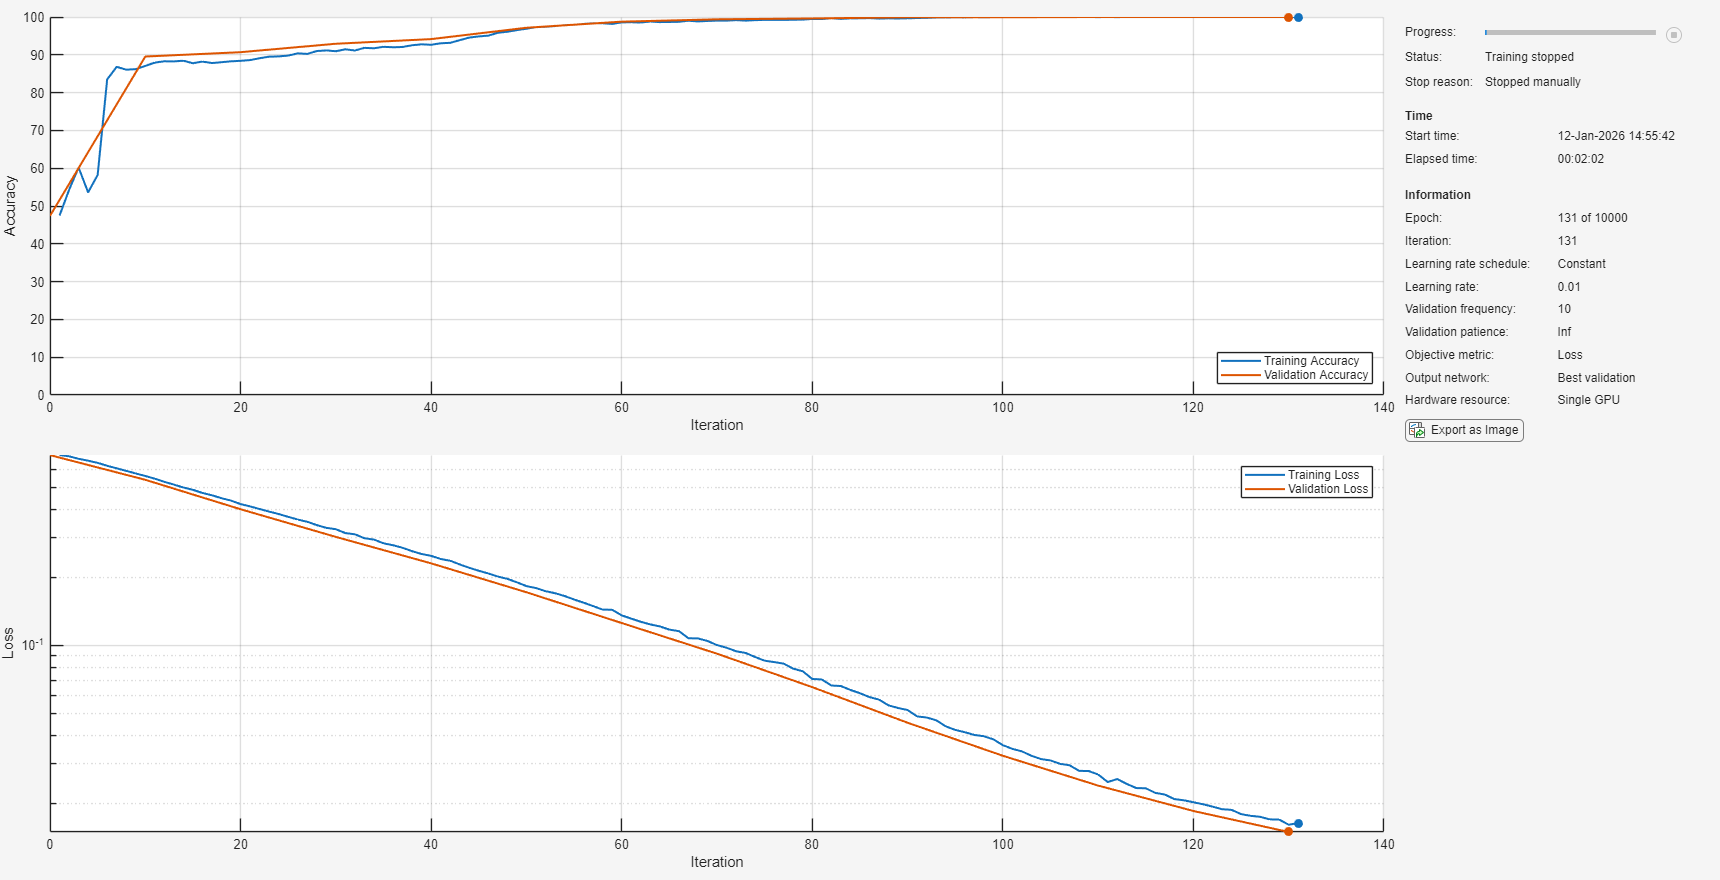

%% train_mushroom_release.m
% Public-ready script for classifying the UCI Mushroom dataset with a
% frozen NAR-style network (two fixed tanh FC blocks + softmax head).
%
% Dataset
% -------
% UCI Machine Learning Repository:
%   "Mushroom"
%   URL: https://archive.ics.uci.edu/dataset/73/mushroom
%
% How to obtain & prepare the data
% --------------------------------
% 1) Manual download (web UI):
%    - Visit the URL above and download the raw file (commonly 'agaricus-lepiota.data').
%    - Put it under: ./data/uci_mushroom/
%    - In MATLAB, run to build the MAT expected by this script:
%         prepare_mushroom_mat_from_uci('./data/uci_mushroom', './data/mushroom_dataset.mat');
%
% 2) If you already have the data file locally:
%       prepare_mushroom_mat_from_uci('/path/to/agaricus-lepiota.data', './data/mushroom_dataset.mat');
%
% Expected MAT file
% -----------------
% This script expects ./data/mushroom_dataset.mat with a numeric matrix
% variable 'data' of shape [N x (1+F)] where:
%   - Column 1 is the encoded class label (1..K)  (original 'e'/'p')
%   - Columns 2..end are the encoded categorical features (integers 1..Ki)
% The helper below reads the raw categorical file and encodes each column
% consistently to integers so it matches this interface exactly.
%
% Usage
% -----
%   train_mushroom_release
%
% Notes
% -----
% * Requires: MATLAB R2023b+ and Deep Learning Toolbox.
% * Custom initializers: uses your original functions
%     customWeights1 / customWeights2 / customWeights3
%   Ensure these are on the MATLAB path (same folder or +package).
% * Plots: keeps MATLAB's training-progress window and shows evaluation
%   confusion matrix; nothing is saved to disk.

%% -------------------- User-configurable section --------------------
DATA_DIR   = './';
MAT_PATH   = fullfile(DATA_DIR, 'mushroom_dataset.mat');
WIDTH      = 16000;   % reduce (e.g., 2048) if memory-constrained
MAX_EPOCHS = 10000;
LR         = 0.01;
MINIBATCH  = 4096;    % large dataset; cap for memory

%% -------------------------- Main routine --------------------------
clearvars -except DATA_DIR MAT_PATH WIDTH MAX_EPOCHS LR MINIBATCH
close all; clc; rng(42,'twister');

% If needed, build the MAT from raw UCI file
if ~isfile(MAT_PATH)
    warning('MAT not found at %s. Attempting to prepare from UCI folder...', MAT_PATH);
    prepare_mushroom_mat_from_uci(fullfile(DATA_DIR,'uci_mushroom'), MAT_PATH);
end

S = load(MAT_PATH);
assert(isfield(S,'data'), 'MAT must contain variable ''data'' as numeric.');
data = S.data;

% Labels and features (labels from column 1)
labels = categorical(data(:,1));
% Guard against NaNs (should not occur after encoding, but keep parity)
data(~isfinite(data)) = 0;
X = data(:,2:end)';  % features C x N

% Normalize features: z-score per channel, then scale by 1/sqrt(C)
C = size(X,1);
X = normalize(X, 2);      % along each row (channel)
X(~isfinite(X)) = 0;
X = X / sqrt(C);

% Split: 80/20 train/test, then 80/20 of train for validation
N = size(X,2);
cv1 = cvpartition(N,'HoldOut',0.2);
XTrainFull = X(:, training(cv1));
YTrainFull = labels(training(cv1));
XTest      = X(:, test(cv1));
YTest      = labels(test(cv1));

cv2 = cvpartition(sum(training(cv1)),'HoldOut',0.2);
XTrain = XTrainFull(:, training(cv2));
YTrain = YTrainFull(training(cv2));
XVal   = XTrainFull(:, test(cv2));
YVal   = YTrainFull(test(cv2));

% Number of classes (should be 2 for e/p)
K = numel(categories(YTrain));

% Define network (two frozen FC tanh layers + softmax output)
% Initializers: customWeights1/2/3
layers = [
    featureInputLayer(size(XTrain,1), Normalization='none')
    fullyConnectedLayer(WIDTH,'WeightLearnRateFactor',0, ...
        'WeightsInitializer',@customWeights1_git,'BiasL2Factor',0,'BiasInitializer','zeros')
    tanhLayer
    fullyConnectedLayer(WIDTH,'WeightLearnRateFactor',0, ...
        'WeightsInitializer',@customWeights2_git,'BiasL2Factor',0,'BiasInitializer','zeros')
    tanhLayer
    fullyConnectedLayer(K, 'Name','output', ...
        'WeightLearnRateFactor',0, ...
        'WeightsInitializer',@customWeights3_git,'BiasL2Factor',0,'BiasInitializer','zeros')
    softmaxLayer];

net = dlnetwork(layers);

% Convert to dlarray
XTrain_dl = dlarray(single(XTrain), 'CB');
XVal_dl   = dlarray(single(XVal),   'CB');

% Training options (keep training-progress; no saving)
options = trainingOptions('adam', ...
    'MaxEpochs', MAX_EPOCHS, ...
    'Metrics', ["accuracy"], ...
    'MiniBatchSize', MINIBATCH, ...
    'InitialLearnRate', LR, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {XVal_dl, YVal}, ...
    'ValidationFrequency', 10, ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment','auto', ...
    'Verbose', 0);

[net, info] = trainnet(XTrain_dl, YTrain, net, 'crossentropy', options); 


% Test-time evaluation
XTest_dl = dlarray(single(XTest), 'CB');
scores = predict(net, XTest_dl);
[~, idx] = max(scores, [], 1);
predictedLabels = categorical(idx(:), 1:K, categories(YTrain));

acc = mean(predictedLabels == YTest);
fprintf('Test Accuracy: %.2f%%\n', 100*acc);

Test Accuracy: 100.00%


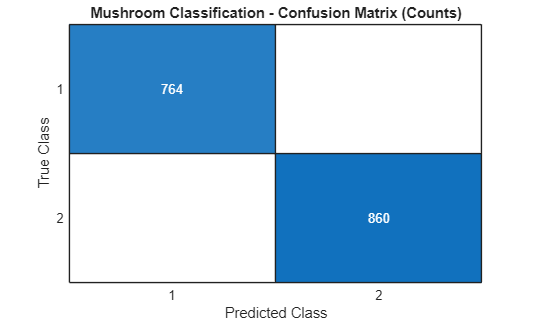


% Confusion matrix (on screen only)
figure('Name','Confusion Matrix (Counts)','Color','w');
confusionchart(YTest, predictedLabels);
title('Mushroom Classification - Confusion Matrix (Counts)');

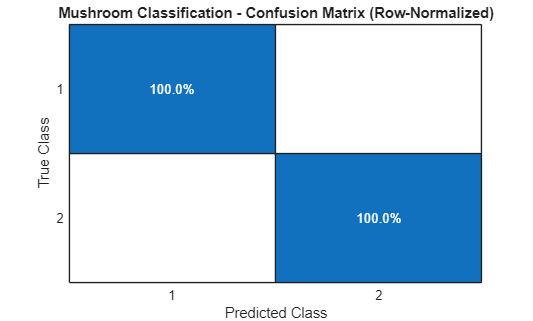


% Row-normalized confusion
figure('Name','Confusion Matrix (Row-Normalized)','Color','w');
confusionchart(YTest, predictedLabels, 'Normalization','row-normalized');
title('Mushroom Classification - Confusion Matrix (Row-Normalized)');


%% ------------------------ Helper functions ------------------------
function prepare_mushroom_mat_from_uci(inDirOrFile, outMat)
% Build ./data/mushroom_dataset.mat with numeric 'data' [N x (1+F)] from
% the raw UCI Mushroom file (agaricus-lepiota.data). Column 1 is class
% ('e'/'p'), others are categorical feature codes. We encode each column
% as integers 1..K (class first), producing a numeric matrix.
    if isfolder(inDirOrFile)
        d = dir(fullfile(inDirOrFile,'*.data'));
        if isempty(d); d = dir(fullfile(inDirOrFile,'*.csv')); end
        assert(~isempty(d), 'No .data or .csv file found in %s', inDirOrFile);
        [~,i] = max([d.bytes]); csvPath = fullfile(d(i).folder, d(i).name);
    else
        csvPath = inDirOrFile;
    end
    assert(isfile(csvPath), 'File not found: %s', csvPath);

    % Read raw, no headers
    T = readtable(csvPath, 'FileType','text', 'ReadVariableNames', false);
    % Expect at least 2 columns (class + features). UCI has 23 columns total.
    assert(width(T) >= 2, 'Expected at least 2 columns');

    % Encode each column to integer codes 1..K using categorical (stable order)
    M = zeros(height(T), width(T));
    for j = 1:width(T)
        cj = categorical(T{:,j});
        [~,~,g] = unique(cj, 'stable');
        M(:,j) = double(g);
    end

    data = M; 
    outDir = fileparts(outMat);
    if ~isempty(outDir) && ~exist(outDir,'dir'); mkdir(outDir); end
    save(outMat,'data','-v7.3');
    fprintf('Wrote %s (rows=%d, cols=%d)\n', outMat, size(M,1), size(M,2));
end
